# Tracciato -> Triangolazione -> Path

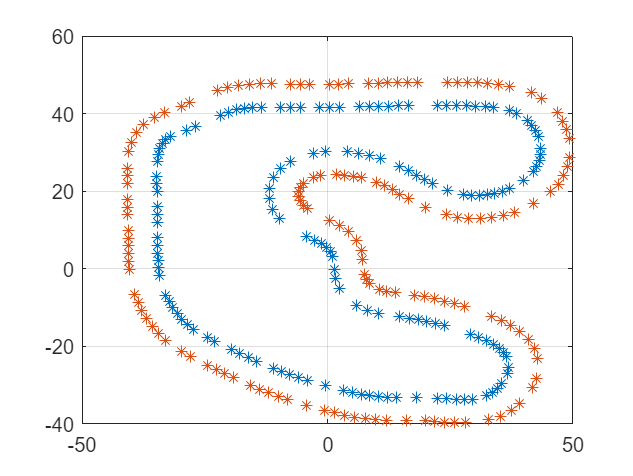

clear all
close all
%% ---TRACCIATO DI RIFERIMENTO ---
    % Circuito Matlab
    load("Circuito-Matlab\track_matlab.mat");

    %% Circuito Semplice
    % load("Circuito-Semplice\track_new.mat");

    % %Circuito FSI
    % load("Circuito-UC\track_autocross.mat")

% Plot circuito
plot(x_in,y_in,'*');
hold on;
grid
plot(x_out,y_out,'*');

## Calcolo del Path

Fonte: 

https://blogs.mathworks.com/student-lounge/2022/10/03/path-planning-for-formula-student-driverless-cars-using-delaunay-triangulation/#respond

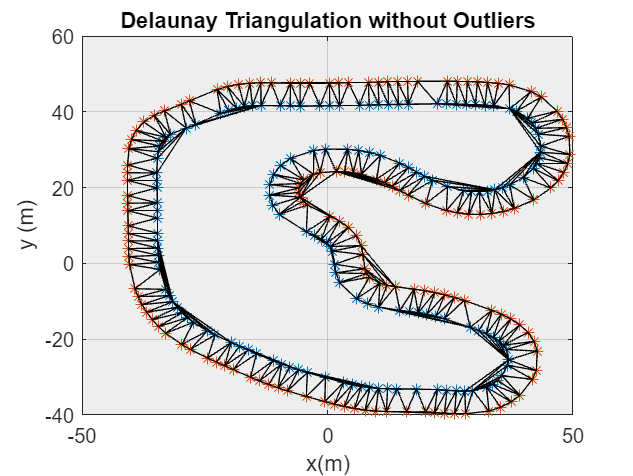

innerConePosition = [x_in,y_in];
outerConePosition = [x_out,y_out];

[m,nc] = size(innerConePosition); % size of the inner/outer cone positions data
P = zeros(2*m,nc); % initiate a P matrix consisting of inner and outer coordinates
P(1:2:2*m,:) = innerConePosition;
P(2:2:2*m,:) = outerConePosition; % merge the inner and outer coordinates with alternate values
xp = []; % create an empty numeric xp vector to store the planned x coordinates after each iteration
yp = []; % create an empty numeric yp vector to store the planned y coordinates after each iteration

interv = 14; % interval
for i = interv:interv:2*m
 DT = delaunayTriangulation(P(((abs((i-1)-interv)):i),:)); % create Delaunay triangulation for abs((i-1)-interv)):i points
 Pl = DT.Points; % coordinates of abs((i-1)-interv)):i vertices
 Cl = DT.ConnectivityList; % triangulation connectivity matrix
 [mc,nc] = size(Pl); % size
 figure(1) % plot delaunay triangulations
 triplot(DT,'k')
 grid on
 ax = gca;
 ax.GridColor = [0, 0, 0]; % [R, G, B]
 xlabel('x(m)')
 ylabel('y (m)')
 set(gca,'Color','#EEEEEE')
 title('Delaunay Triangulation')
 hold on

 % inner and outer constraints when the interval is even
 if rem(interv,2) == 0
 cIn = [2 1;(1:2:mc-3)' (3:2:(mc))'; (mc-1) mc];
 cOut = [(2:2:(mc-2))' (4:2:mc)'];
 else
 % inner and outer constraints when the interval is odd
 cIn = [2 1;(1:2:mc-2)' (3:2:(mc))'; (mc-1) mc];
 cOut = [(2:2:(mc-2))' (4:2:mc)'];
 end
 C = [cIn;cOut]; % create a matrix connecting the constraint boundaries

 TR = delaunayTriangulation(Pl,C); % Delaunay triangulation with constraints
 TRC = TR.ConnectivityList; % triangulation connectivity matrix

 TL = isInterior(TR); % logical values that indicate whether the triangles are inside the bounded region
 TC = TR.ConnectivityList(TL,:); % triangulation connectivity matrix

 [~,pt] = sort(sum(TC,2)); % optional step. The rows of connectivity matrix are arranged in ascending sum of rows...
 % This ensures that the triangles are connected in progressive order.
 TS = TC(pt,:); % connectivity matrix based on ascending sum of rows
 TO = triangulation(TS,Pl); % create triangulations based on sorted connectivity matrix
 figure(2) % plot delaunay triangulations
 triplot(TO,'k')
 grid on
 ax = gca;
 ax.GridColor = [0, 0, 0]; % [R, G, B]
 xlabel('x(m)')
 ylabel('y (m)')
 set(gca,'Color','#EEEEEE')
 title('Delaunay Triangulation without Outliers')
 hold on

 xPo = TO.Points(:,1);
 yPo = TO.Points(:,2);
 E = edges(TO); % triangulation edges
 iseven = rem(E, 2) == 0; % neglect boundary edges
 Eeven = E(any(iseven,2),:);
 isodd = rem(Eeven,2) ~=0;
 Eodd = Eeven(any(isodd,2),:);
 xmp = ((xPo((Eodd(:,1))) + xPo((Eodd(:,2))))/2); % x coordinate midpoints
 ymp = ((yPo((Eodd(:,1))) + yPo((Eodd(:,2))))/2); % y coordinate midpoints
 Pmp = [xmp ymp]; % midpoint coordinates

 distancematrix = squareform(pdist(Pmp));
 distancesteps = zeros(length(Pmp)-1,1);
 for j = 2:length(Pmp)
     distancesteps(j-1,1) = distancematrix(j,j-1);
 end
 totalDistance = sum(distancesteps); % total distance travelled
 distbp = cumsum([0; distancesteps]); % distance for each waypoint
 gradbp = linspace(0,totalDistance,100);
 xq = interp1(distbp,xmp,gradbp,'spline'); % interpolate x coordinates
 yq = interp1(distbp,ymp,gradbp,'spline'); % interpolate y coordinates
 xp = [xp xq]; % store obtained x midpoints after each iteration
 yp = [yp yq]; % store obtained y midpoints after each iteration

 figure(3)
 % subplot
 pos1 = [0.1 0.15 0.5 0.7];
 subplot('Position',pos1)
 pathPlanPlot(innerConePosition,outerConePosition,P,DT,TO,xmp,ymp,cIn,cOut,xq,yq)
 title(['Path planning based on constrained Delaunay' newline ' triangulation'])
 % subplot
 pos2 = [0.7 0.15 0.25 0.7];
 subplot('Position',pos2)
 pathPlanPlot(innerConePosition,outerConePosition,P,DT,TO,xmp,ymp,cIn,cOut,xq,yq)
 xlim([min(min(xPo(1:2:(mc-1)),xPo(2:2:mc))) max(max(xPo(1:2:(mc-1)),xPo(2:2:mc)))])
 ylim([min(min(yPo(1:2:(mc-1)),yPo(2:2:mc))) max(max(yPo(1:2:(mc-1)),yPo(2:2:mc)))])
end

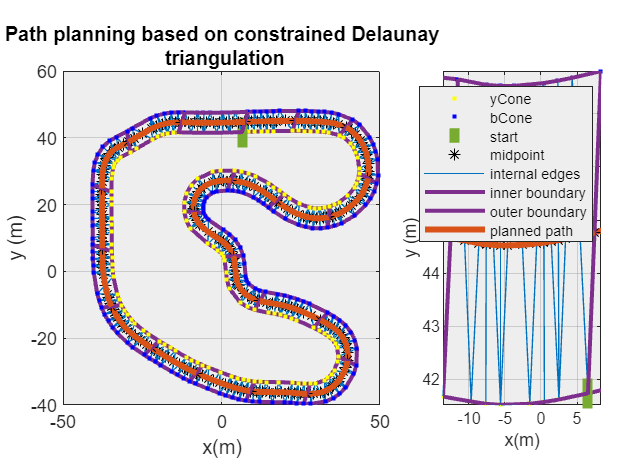


h = legend('yCone','bCone','start','midpoint','internal edges',...
 'inner boundary','outer boundary','planned path');

Pp = [xp' yp']; % concatenated planned path
% save Circuito-Semplice\Point_New_Circ_600 xp yp Pp
